# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240212'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'social_multiflavor_foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14633','14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,2,0,0; 2,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14633 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14633\20240212_081836_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14633" -interp 0
Using the following workspace file:  "20240212_081836_merged.trodesconf"
Exporting data...
6.573%13.15%19.72%26.29%32.86%39.43%46.01%52.58%59.15%65.72%72.29%A gap of 74 packets occured in the file. Last timestamp:  21358507 (Clock is:  "00:11:51" )
78.87%85.44%92.01%98.58%Done



chanmap_file = struct with fields:
       name: '20240212_081836_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14633\20240212_081836_merged.kilosort'
       date: '13-Feb-2024 07:45:18'
      bytes: 5242
      isdir: 0
    datenum: 7.3930e+05


Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662\20240212_081836_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662" -interp 0
Using the following workspace file:  "20240212_081836_merged.trodesconf"
Exporting data...
1.594%A gap of 88 packets occured in the file. Last timestamp:  4631247 (Clock is:  "00:02:34" )
A gap of 8 packets occured in the file. Last timestamp:  4631577 (Clock is:  "00:02:34" )
3.188%4.782%6.376%7.97%9.564%11.16%A gap of 2 packets occured in the file. Last timestamp:  14699997 (Clock is:  "00:08:09" )
12.75%14.35%A gap of 2 packets occured in t

chanmap_file = struct with fields:
       name: '20240212_081836_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662\20240212_081836_merged.kilosort'
       date: '13-Feb-2024 08:03:14'
      bytes: 2518
      isdir: 0
    datenum: 7.3930e+05


chanmap_file = struct with fields:
       name: '20240212_081836_merged.channelmap_probe2.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662\20240212_081836_merged.kilosort'
       date: '13-Feb-2024 08:03:14'
      bytes: 3358
      isdir: 0
    datenum: 7.3930e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14633\20240212_081836_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   5s. Loading raw data and applying filters... 
Time  98s. Finished preprocessing 209 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.39 sec, 1 batches, 5891 spikes 
39.25 sec, 101 batches, 830152 spikes 
80.39 sec, 201 batches, 1653023 spikes 
83.90 sec, 209 batches, 1725895 spikes 


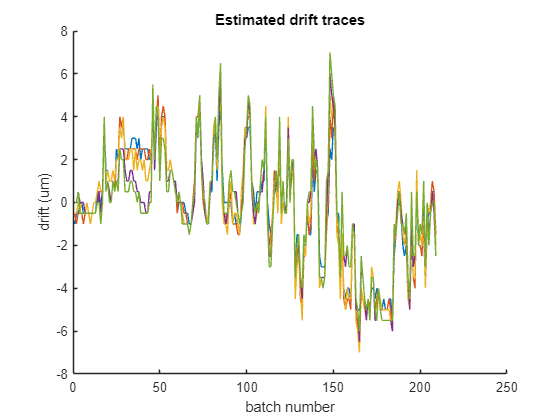

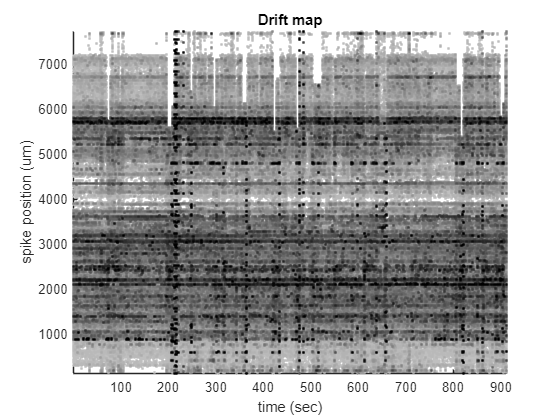

time 155.40, Shifted up/down 209 batches. 
0.44 sec, 1 batches, 10000 spikes 
36.57 sec, 101 batches, 1010000 spikes 
72.46 sec, 201 batches, 2010000 spikes 
75.41 sec, 209 batches, 2090000 spikes 
time 0.00, GROUP 1/384, units 0 
time 2.59, GROUP 6/384, units 21 
time 4.52, GROUP 11/384, units 36 
time 5.26, GROUP 16/384, units 41 
time 6.63, GROUP 21/384, units 50 
time 8.71, GROUP 26/384, units 61 
time 9.79, GROUP 31/384, units 67 
time 11.94, GROUP 36/384, units 78 
time 13.47, GROUP 41/384, units 86 
time 15.06, GROUP 46/384, units 93 
time 17.70, GROUP 51/384, units 107 
time 19.55, GROUP 56/384, units 118 
time 20.95, GROUP 61/384, units 127 
time 22.71, GROUP 66/384, units 139 
time 24.20, GROUP 71/384, units 151 
time 26.57, GROUP 76/384, units 170 
time 28.55, GROUP 81/384, units 187 
time 29.92, GROUP 86/384, units 198 
time 31.18, GROUP 91/384, units 209 
time 31.59, GROUP 96/384, units 215 
time 32.53, GROUP 101/384, units 223 
time 35.46, GROUP 106/384, units 243 
time 3

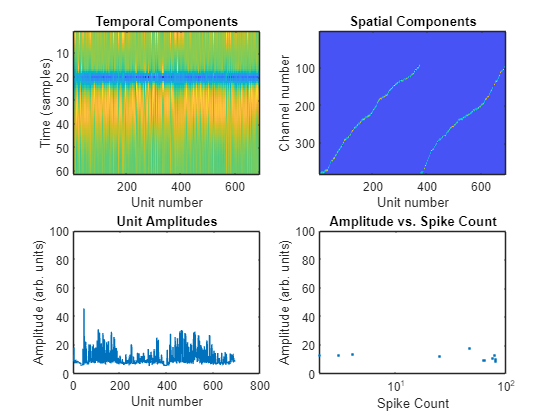

time 0.00, GROUP 1/384, units 0 
time 0.01, GROUP 6/384, units 0 
time 0.01, GROUP 11/384, units 0 
time 0.01, GROUP 16/384, units 0 
time 0.02, GROUP 21/384, units 0 
time 0.02, GROUP 26/384, units 0 
time 0.02, GROUP 31/384, units 0 
time 0.03, GROUP 36/384, units 0 
time 0.03, GROUP 41/384, units 0 
time 0.03, GROUP 46/384, units 0 
time 0.03, GROUP 51/384, units 0 
time 0.04, GROUP 56/384, units 0 
time 0.04, GROUP 61/384, units 0 
time 0.04, GROUP 66/384, units 0 
time 0.04, GROUP 71/384, units 0 
time 0.05, GROUP 76/384, units 0 
time 0.05, GROUP 81/384, units 0 
time 0.05, GROUP 86/384, units 0 
time 0.05, GROUP 91/384, units 0 
time 0.06, GROUP 96/384, units 0 
time 0.88, GROUP 101/384, units 6 
time 1.90, GROUP 106/384, units 13 
time 2.91, GROUP 111/384, units 21 
time 4.60, GROUP 116/384, units 31 
time 7.29, GROUP 121/384, units 43 
time 9.92, GROUP 126/384, units 55 
time 13.32, GROUP 131/384, units 70 
time 18.60, GROUP 136/384, units 87 
time 23.06, GROUP 141/384, units 

ans = 119

initialized spike counts
merged 86 into 82 
merged 339 into 329 
merged 264 into 272 
merged 265 into 272 
merged 267 into 272 
merged 275 into 274 
merged 266 into 272 
merged 171 into 170 
merged 84 into 82 
merged 100 into 102 
merged 308 into 300 
merged 39 into 42 
merged 169 into 166 
merged 99 into 98 
merged 263 into 258 


ans = 110

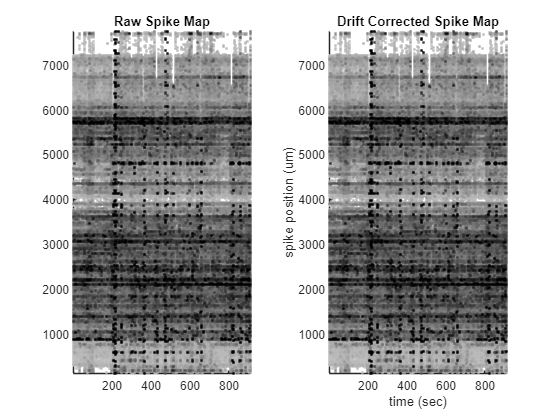

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [209×1 double]
             dshift: [209×5 double]
                st0: [1725895×6 double]
                  F: [1534×20×209 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662\20240212_081836_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   7s. Loading raw data and applying filters... 
Time 187s. Finished preprocessing 861 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1402

0.17 sec, 1 batches, 3087 spikes 
17.32 sec, 101 batches, 351633 spikes 
35.15 sec, 201 batches, 745932 spikes 
54.43 sec, 301 batches, 1126691 spikes 
75.07 sec, 401 batches, 1474121 spikes 
97.16 sec, 501 batches, 1806271 spikes 
120.71 sec, 601 batches, 2123660 spikes 
145.80 sec, 701 batches, 2443793 spikes 
172.61 sec, 801 batches, 2742663 spikes 
189.23 sec, 861 batches, 2926356 spikes 


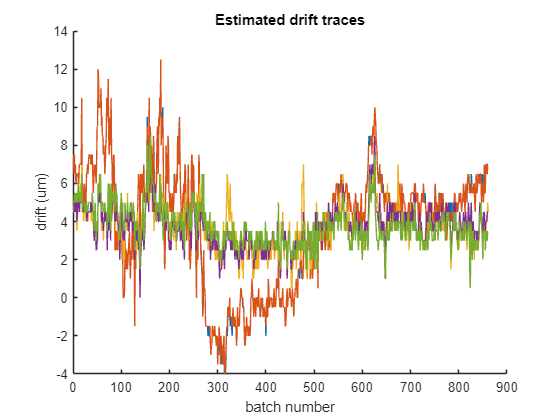

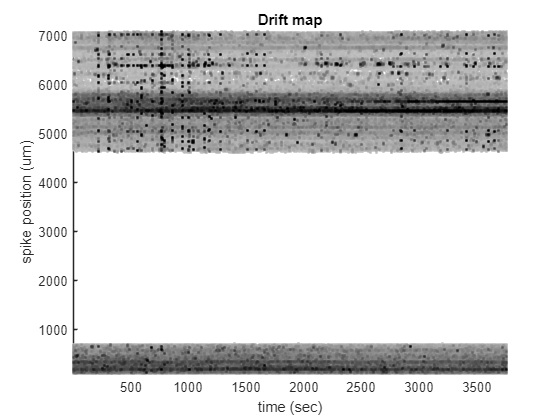

time 443.60, Shifted up/down 861 batches. 
0.25 sec, 1 batches, 8088 spikes 
24.92 sec, 101 batches, 896848 spikes 
49.68 sec, 201 batches, 1857477 spikes 
74.52 sec, 301 batches, 2835813 spikes 
99.20 sec, 401 batches, 3835216 spikes 
123.94 sec, 501 batches, 4824043 spikes 
149.06 sec, 601 batches, 5716174 spikes 
173.80 sec, 701 batches, 6591013 spikes 
198.53 sec, 801 batches, 7474462 spikes 
214.07 sec, 861 batches, 8014307 spikes 
time 0.00, GROUP 1/352, units 0 
time 2.63, GROUP 6/352, units 10 
time 3.97, GROUP 11/352, units 15 
time 5.24, GROUP 16/352, units 20 
time 5.44, GROUP 21/352, units 21 
time 5.45, GROUP 26/352, units 21 
time 5.45, GROUP 31/352, units 21 
time 5.45, GROUP 36/352, units 21 
time 5.45, GROUP 41/352, units 21 
time 5.45, GROUP 46/352, units 21 
time 5.45, GROUP 51/352, units 21 
time 5.45, GROUP 56/352, units 21 
time 5.45, GROUP 61/352, units 21 
time 5.45, GROUP 66/352, units 21 
time 5.45, GROUP 71/352, units 21 
time 5.45, GROUP 76/352, units 21 
ti

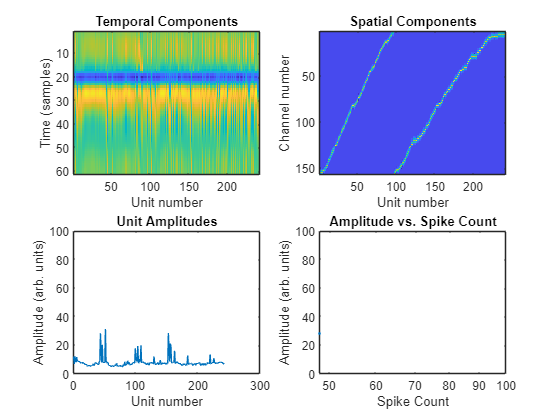

time 0.00, GROUP 1/352, units 0 
time 0.01, GROUP 6/352, units 0 
time 0.01, GROUP 11/352, units 0 
time 0.01, GROUP 16/352, units 0 
time 0.02, GROUP 21/352, units 0 
time 0.02, GROUP 26/352, units 0 
time 0.02, GROUP 31/352, units 0 
time 0.02, GROUP 36/352, units 0 
time 0.03, GROUP 41/352, units 0 
time 0.03, GROUP 46/352, units 0 
time 0.03, GROUP 51/352, units 0 
time 0.04, GROUP 56/352, units 0 
time 0.04, GROUP 61/352, units 0 
time 0.04, GROUP 66/352, units 0 
time 0.04, GROUP 71/352, units 0 
time 0.05, GROUP 76/352, units 0 
time 0.05, GROUP 81/352, units 0 
time 0.05, GROUP 86/352, units 0 
time 0.05, GROUP 91/352, units 0 
time 0.06, GROUP 96/352, units 0 
time 0.06, GROUP 101/352, units 0 
time 0.06, GROUP 106/352, units 0 
time 0.06, GROUP 111/352, units 0 
time 0.53, GROUP 116/352, units 3 
time 2.73, GROUP 121/352, units 15 
time 5.09, GROUP 126/352, units 24 
time 6.43, GROUP 131/352, units 29 
time 9.23, GROUP 136/352, units 36 
time 15.12, GROUP 141/352, units 45 
t

ans = 11

initialized spike counts
merged 35 into 34 
merged 125 into 122 


ans = 10

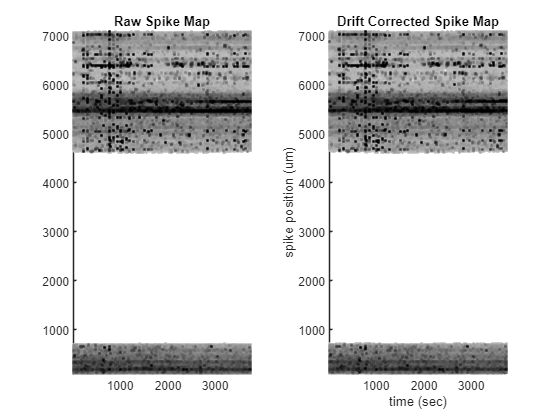

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [157×1 double]
                 yc: [157×1 double]
            xcoords: [157×1 double]
            ycoords: [157×1 double]
               Wrot: [157×157 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×157 gpuArray]
               dist: [10×1408 single]
              iorig: [861×1 double]
             dshift: [861×5 double]
                st0: [2926356×6 double]
                  F: [1402×20×861 double]
                 F0: [1402×20 gpuArray]
                F0m: [1402×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×1408 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240212\ephys\20240212_081836.rec\14662\20240212_081836_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   9s. Loading raw data and applying filters... 
Time 253s. Finished preprocessing 861 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

   906

0.23 sec, 1 batches, 4220 spikes 
24.74 sec, 101 batches, 528797 spikes 
50.40 sec, 201 batches, 1139936 spikes 
77.82 sec, 301 batches, 1736695 spikes 
107.27 sec, 401 batches, 2248318 spikes 
138.81 sec, 501 batches, 2768067 spikes 
172.35 sec, 601 batches, 3256843 spikes 
207.76 sec, 701 batches, 3741863 spikes 
245.23 sec, 801 batches, 4188396 spikes 
268.64 sec, 861 batches, 4448568 spikes 


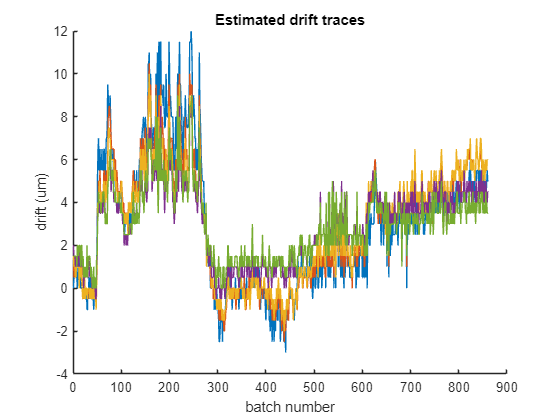

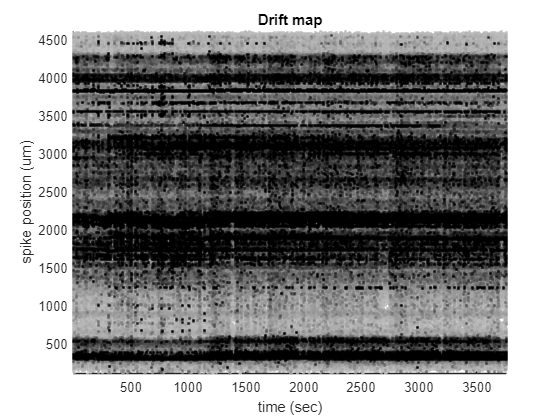

time 628.85, Shifted up/down 861 batches. 
0.39 sec, 1 batches, 10000 spikes 
35.69 sec, 101 batches, 1000554 spikes 
70.81 sec, 201 batches, 1993985 spikes 
106.14 sec, 301 batches, 2988815 spikes 
141.28 sec, 401 batches, 3988815 spikes 
176.47 sec, 501 batches, 4988815 spikes 
212.00 sec, 601 batches, 5987500 spikes 
247.15 sec, 701 batches, 6973385 spikes 
282.28 sec, 801 batches, 7922039 spikes 
304.11 sec, 861 batches, 8476907 spikes 
time 0.00, GROUP 1/228, units 0 
time 1.35, GROUP 6/228, units 9 
time 5.42, GROUP 11/228, units 25 
time 8.09, GROUP 16/228, units 38 
time 9.96, GROUP 21/228, units 47 
time 11.70, GROUP 26/228, units 55 
time 14.02, GROUP 31/228, units 65 
time 16.00, GROUP 36/228, units 74 
time 19.00, GROUP 41/228, units 88 
time 20.94, GROUP 46/228, units 95 
time 23.44, GROUP 51/228, units 104 
time 28.59, GROUP 56/228, units 124 
time 31.67, GROUP 61/228, units 135 
time 33.32, GROUP 66/228, units 141 
time 35.43, GROUP 71/228, units 149 
time 36.73, GROUP 7

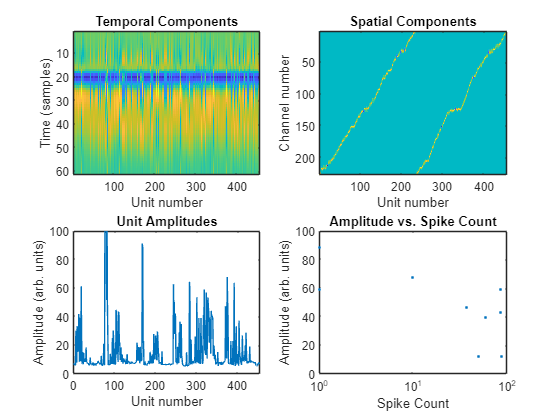

time 0.00, GROUP 1/228, units 0 
time 0.01, GROUP 6/228, units 0 
time 0.01, GROUP 11/228, units 0 
time 0.02, GROUP 16/228, units 0 
time 0.02, GROUP 21/228, units 0 
time 0.03, GROUP 26/228, units 0 
time 0.03, GROUP 31/228, units 0 
time 0.04, GROUP 36/228, units 0 
time 0.04, GROUP 41/228, units 0 
time 0.05, GROUP 46/228, units 0 
time 0.05, GROUP 51/228, units 0 
time 0.06, GROUP 56/228, units 0 
time 0.06, GROUP 61/228, units 0 
time 0.06, GROUP 66/228, units 0 
time 0.07, GROUP 71/228, units 0 
time 0.07, GROUP 76/228, units 0 
time 0.08, GROUP 81/228, units 0 
time 0.08, GROUP 86/228, units 0 
time 0.09, GROUP 91/228, units 0 
time 0.09, GROUP 96/228, units 0 
time 6.61, GROUP 101/228, units 24 
time 10.90, GROUP 106/228, units 35 
time 14.80, GROUP 111/228, units 46 
time 17.10, GROUP 116/228, units 55 
time 26.88, GROUP 121/228, units 79 
time 34.86, GROUP 126/228, units 93 
time 37.77, GROUP 131/228, units 103 
time 40.62, GROUP 136/228, units 115 
time 42.50, GROUP 141/228

ans = 85

initialized spike counts
merged 295 into 287 
merged 15 into 18 
merged 298 into 292 
merged 303 into 291 
merged 157 into 156 
merged 14 into 18 
merged 8 into 18 
merged 285 into 293 
merged 296 into 287 
merged 81 into 69 
merged 10 into 18 
merged 205 into 195 
merged 196 into 208 


ans = 76

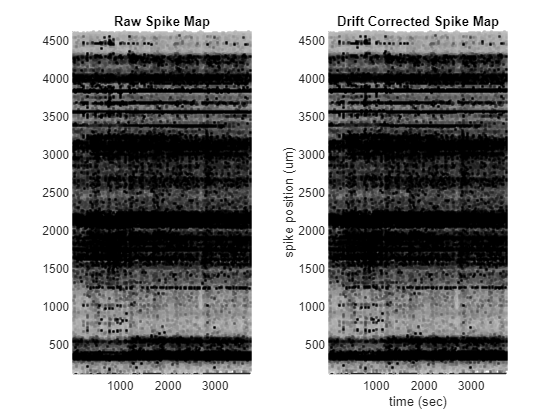

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [227×1 double]
                 yc: [227×1 double]
            xcoords: [227×1 double]
            ycoords: [227×1 double]
               Wrot: [227×227 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×227 gpuArray]
               dist: [10×2038 single]
              iorig: [861×1 double]
             dshift: [861×5 double]
                st0: [4448568×6 double]
                  F: [906×20×861 double]
                 F0: [906×20 gpuArray]
                F0m: [906×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×2038 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 16 

for bb = 1:length(bname_ephys)
    path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec',bname_ephys{bb},'*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
    chanmap_file = dir(fullfile(path_to_rec_dir,'*.kilosort','channelmap_probe*'));
    for probeNum = 1:length(chanmap_file)
        chanmap = load(fullfile(chanmap_file(probeNum).folder,chanmap_file(probeNum).name));
        numChannels = length(chanmap.chanMap);
        runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)
    end
end


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);